# 测试（间接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]'; % m, m/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 0.1; % s
p.f = 0.01; % N/kg; m/s^2

### 能量最优

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    2.179119e+06    2.996e+07    8.941e-08
    1      14    8.486741e-02    7.598e-01    2.561e+08    2.334e-02


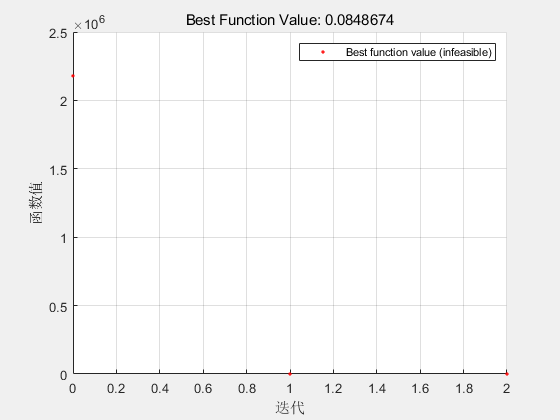


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s,fval,exitflag,output] = IndirOptEnergy(@CwEnergyOpt, x0, xf, tf, p);

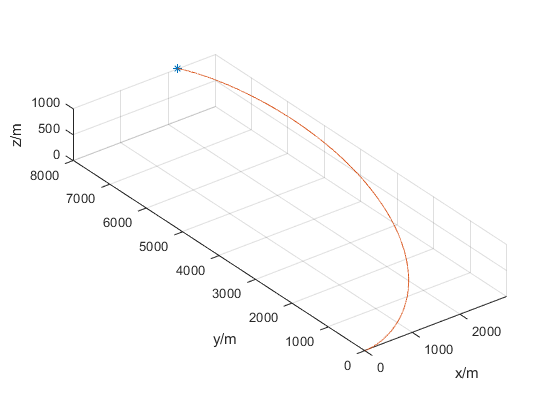

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

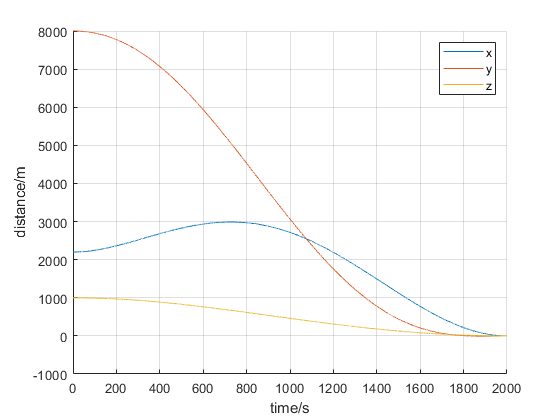

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

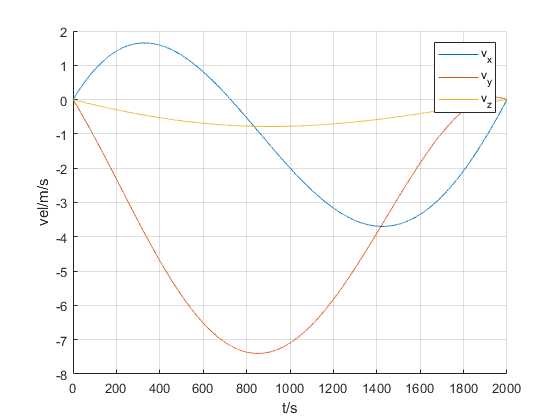

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

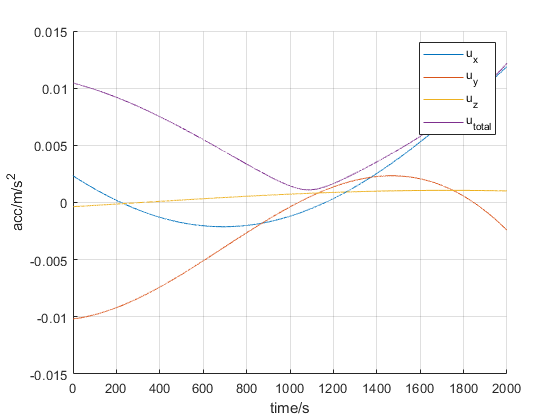

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优（同伦）

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.447791e-03    1.341e+04    3.331e-16
    1      14    8.194290e-02    4.761e+01    5.799e+04    2.091e+02
    2      21    8.506378e-02    1.153e+00    1.402e+03    4.267e+00
    3      28    8.521574e-02    1.363e-03    2.415e+01    2.010e-01
    4      35    8.521575e-02    2.439e-10    2.530e-03    9.911e-06
    5      42    8.521575e-02    3.934e-12    7.763e-09    1.653e-12

Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the <a h

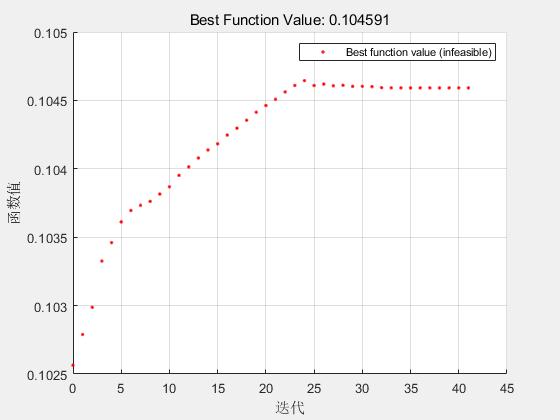


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptFuel(@CwFuelOpt, x0, xf, tf, p);

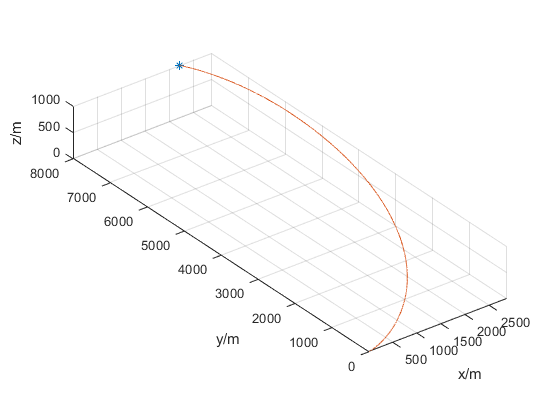

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

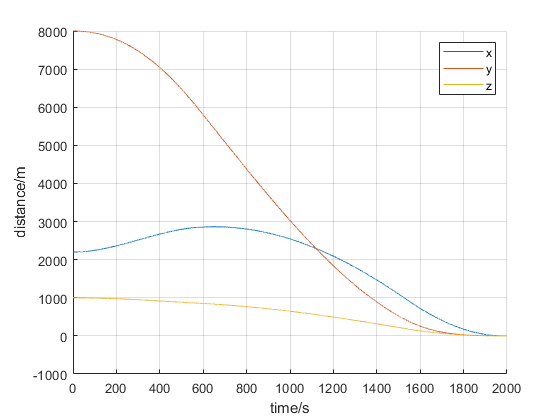

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

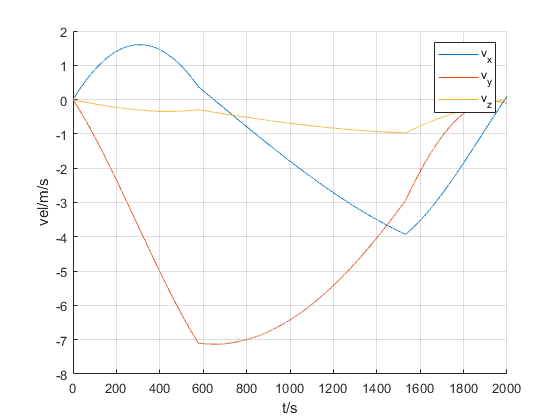

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

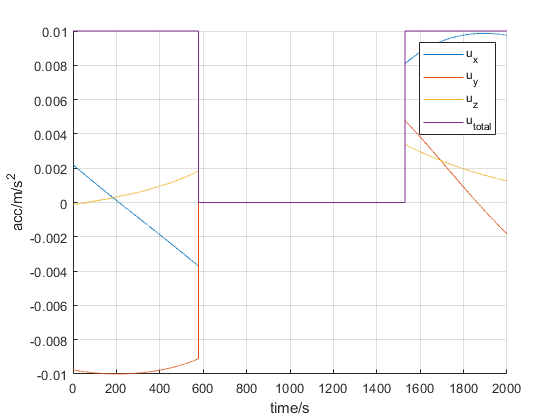

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostEnergy: $\int 1 \mathrm{d}t$

[s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime2(@CwTimeOpt3, x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwEnergyOpt(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime3(@(t, x) CwTimeOpt2(t, x, p), x0, xf, tf, p);
figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off
figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off
figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off
figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off